# Compare Airspeed

## Load SF data

SF = readtable('SF/Track.csv');
SF.Code = categorical(SF.Code);

Convert speed in complex

SF.ground = SF.Vg/100 .* exp( mod(-deg2rad(SF.Rg)+90,360)*1i );
SF.wind   = SF.Vw/100 .* exp( mod(-deg2rad(SF.Rw)+90,360)*1i );
SF.air    = SF.Va/100 .* exp( mod(-deg2rad(SF.Ra)+90,360)*1i ); 

Add seasonal variables

season = [50 175 320 Inf]; % day of year
season_label = {'Spring (20-Feb  - 25-June)','Autumn (25-June - 17-Nov)','Winter (17-Nov - 20-Feb)'};
SF.season=sum(bsxfun(@gt, day(SF.Date,'dayofyear'), season),2);
SF.season(SF.season==0)=4;

Define parameter of histogram

norm = 'pdf';
edge_angle=32;
edge_hist = 0:40;

## Initial Visualization of Dataset

Date

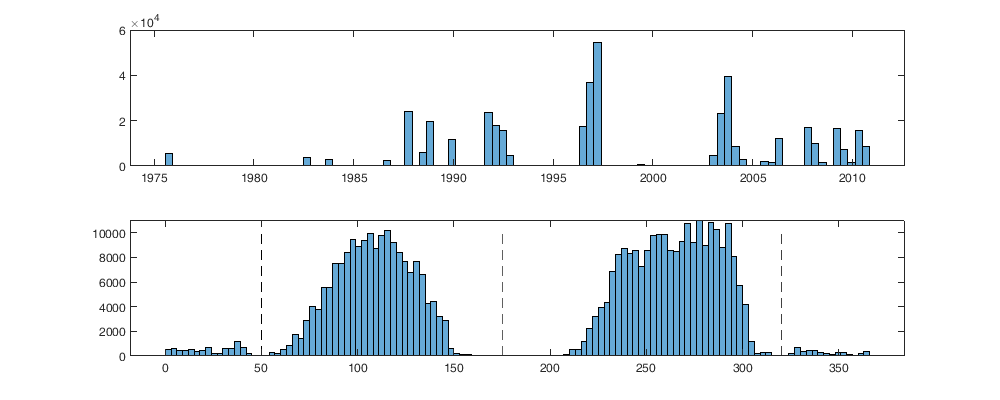

figure('position',[0 0 1000 400]);
subplot(2,1,1); histogram(SF.Date)
subplot(2,1,2); histogram(day(SF.Date,'dayofyear')); hold on;
plot([season; season],[0 10000],'--k')

Speed

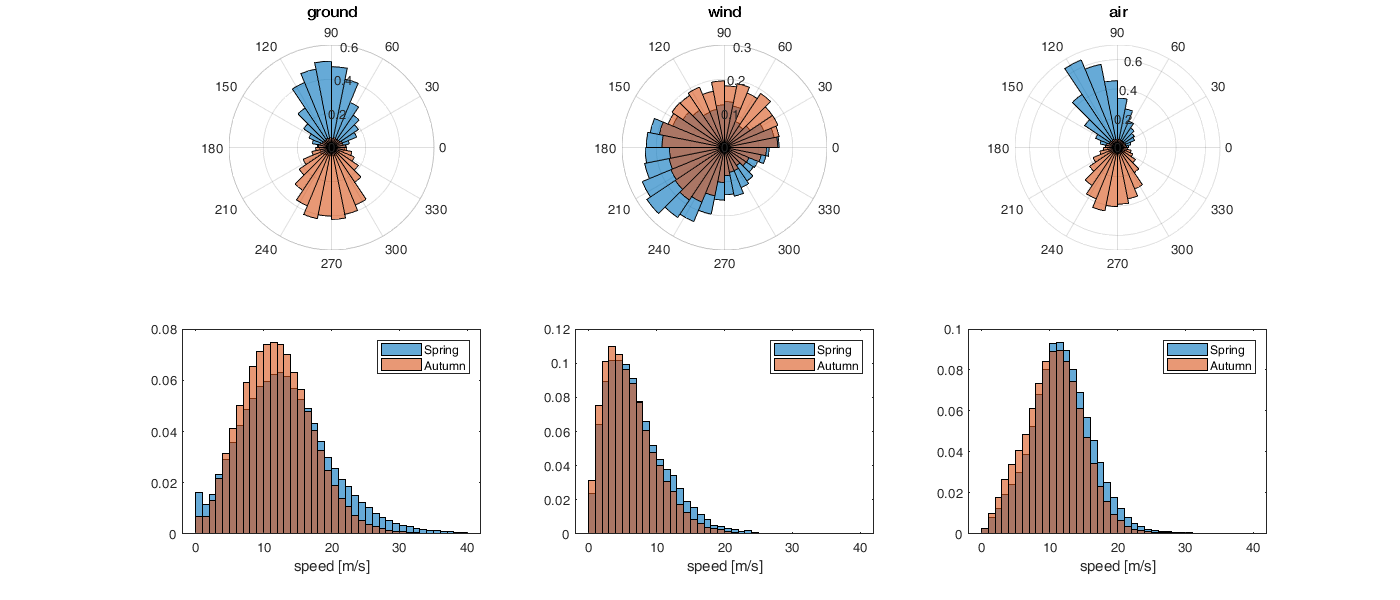

l = {'ground','wind','air'};
s = [1 2];
figure('position',[0 0 1400 600])
for i_l=1:numel(l)
    for i_s=1:numel(s)
        subplot(2,3,i_l)
        polarhistogram(angle(SF.(l{i_l})(SF.season==s(i_s))),edge_angle,'Normalization',norm); hold on;
        title(l{i_l});
        subplot(2,3,i_l+numel(l))
        histogram(abs(SF.(l{i_l})(SF.season==s(i_s))),edge_hist,'Normalization',norm); hold on;
    end
    legend({'Spring','Autumn'}); xlabel('speed [m/s]')
end

## Nighly average

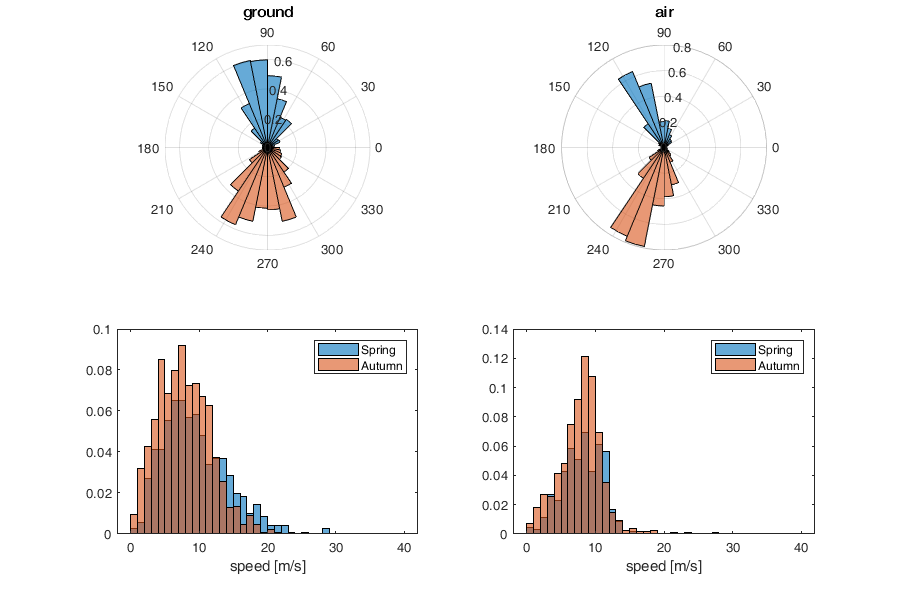

l = {'ground','air'};
s = [1 2];

figure('position',[0 0 900 600])
for i_l=1:numel(l)
    for i_s=1:numel(s)
        [G,G_date, G_code] = findgroups(dateshift(SF.Date(SF.season==s(i_s)),'start','day') , SF.Code(SF.season==s(i_s)));
        tmp = splitapply(@mean, SF.(l{i_l})(SF.season==s(i_s)), G);
        
        subplot(2,2,i_l)
        polarhistogram(angle(tmp),edge_angle,'Normalization',norm); hold on;
        title(l{i_l});
        subplot(2,2,i_l+numel(l))
        histogram(abs(tmp),edge_hist,'Normalization',norm); hold on;
    end
    legend({'Spring','Autumn'}); xlabel('speed [m/s]')
end

## Averaging produced by WR

Roughly accounting for volume size difference with WR

Radius of weather radar (WR) and birdscan (BS). We compute the average beam width from the beam angle and the height used

rWR = 25;
baBS = 17.5;% beam angle deg
rBS = @(h) h*tand(baBS);

Volume covered by WR (no coverage within first 5km

VWR = rWR^2*pi-5^2*pi

VWR = 1.8850e+03

VBS = rBS(maxalt/1000)^2*pi*maxalt/1000/3 - rBS(minalt/1000)^2*pi*minalt/1000/3

VBS = 0.0130

The duration can be found from speed.

dtBS = @(v) (VWR - VBS) / (2*rBS((maxalt+minalt)/2/1000)*v);

Assume a initial bird speed of 10 m/s -> 864 km/day

dtBS(10/1000*60*60*24)

ans = 12.5805

dtBS(20/1000*60*60*24)

ans = 6.2903

This would require to do average over 10+ days. NOT POSSIBLE

Attempt to upscale the distribution

Qin=nan(2,numel(t),4); % Individual
Qan=nan(2,numel(t),4); % aggregated
nb_day=nan(numel(t),2);
for i_t=1:numel(t)
    for i_isBird=0:1
        tmp=SF.ground(SF.day_id==i_t & SF.isBird==i_isBird);
        if (size(tmp,1))>50 % minimum number of tracks to consider the night
            Qin(i_isBird+1,i_t,1)=mean(abs(tmp));
            Qin(i_isBird+1,i_t,2)=quantile(abs(tmp),.1);
            Qin(i_isBird+1,i_t,3)=quantile(abs(tmp),.9);
            Qin(i_isBird+1,i_t,4)=std(tmp);
            
            nb_day(i_t,i_isBird+1) = dtBS(mean(abs(tmp))/1000*60*60*24);
            
            [f,xi] = ksdensity([real(tmp) imag(tmp)]);
            
            xiid = datasample(1:numel(f),round(nb_day(i_t,i_isBird+1)*size(tmp,1)),'weight',f);
            
            SimSam = xi(xiid,1) + xi(xiid,2)*1i;
            Qan(i_isBird+1,i_t,1)=abs(mean(SimSam));
            Qan(i_isBird+1,i_t,2)=abs(quantile(SimSam,0.1));
            Qan(i_isBird+1,i_t,3)=abs(quantile(SimSam,0.9));
            % The radar only capture the radial velocity, on which a linear fit is performed. 
            % Radial velocity is compute here by projecting the speed vector on all possible angle of radar beam. 
            % In practice this is computed by the mean projection factor assuming a uniforme distribution of radar beam angle from 0-360 (or 0 to pi/2 as the expected value is the same from 0 to 2pi)
            % E[cos(x)]_0^{pi/2} = 2/pi
            Qan(i_isBird+1,i_t,4)=std(2/pi .* abs(SimSam)); 
        end
    end
end

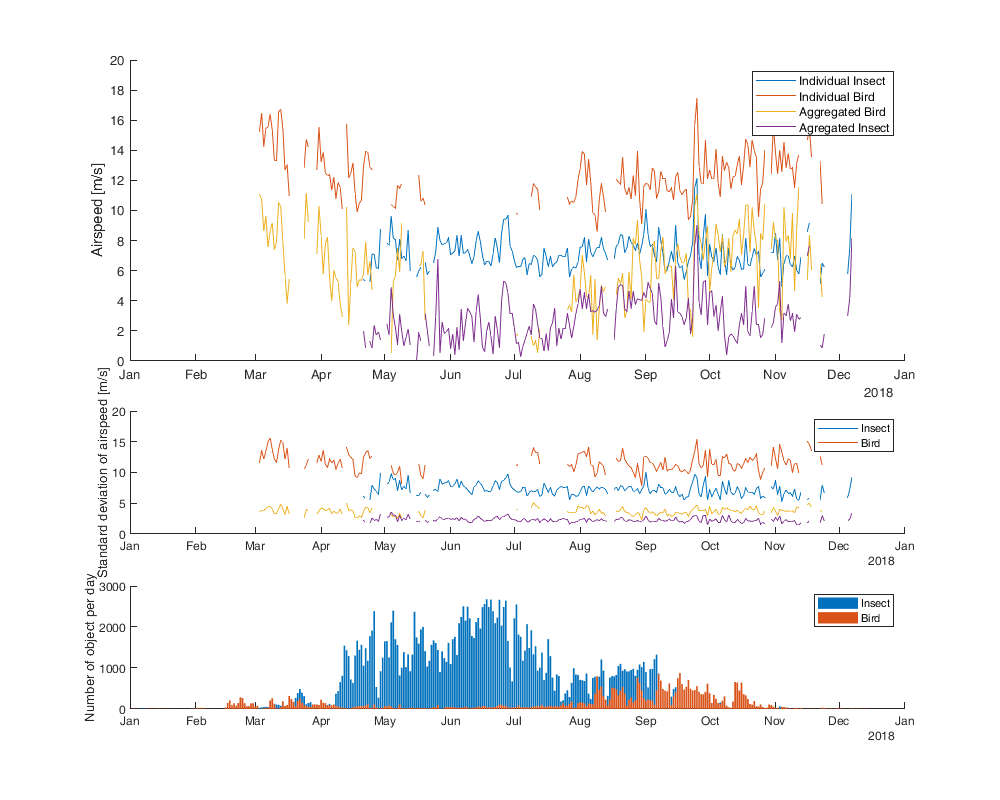

figure('position',[0 0 1000 800]); 
subplot(4,1,[1 2]);hold on;
%plot(t,Y)
%legend({'Mean of flight speed over day', 'Speed of flight mean over day', 'Mean of flight speed for volume', 'Speed of flight mean for volume'})

idt=~any(isnan(Qin(:,:,1)));
%fill([t(idt), fliplr(t(idt))], [Y(1,idt,2), fliplr(Y(1,idt,3))],'b','FaceAlpha',.2,'EdgeColor','none')
%fill([t(idt), fliplr(t(idt))], [Y(4,idt,2), fliplr(Y(4,idt,3))],'r','FaceAlpha',.2,'EdgeColor','none')
plot(t,Qin(1,:,1)); 
plot(t,Qin(2,:,1)); 
plot(t,Qan(2,:,1)); 
plot(t,Qan(1,:,1)); 
legend({'Individual Insect','Individual Bird','Aggregated Bird','Agregated Insect'})
ylim([0 20]); xlim([t(1) t(end)]); ylabel('Airspeed [m/s]')
subplot(4,1,3); hold on; 
plot(t,Qin(1,:,4))
plot(t,Qin(2,:,4))
plot(t,Qan(2,:,4))
plot(t,Qan(1,:,4))
legend({'Insect','Bird'})
xlim([t(1) t(end)]);  ylabel('Standard deviation of airspeed [m/s]')
subplot(4,1,4); hold on;
bar(t,histcounts(findgroups(SF.day_id(~SF.isBird)),0.5:1:numel(t)+0.5))
bar(t,histcounts(findgroups(SF.day_id(SF.isBird)),0.5:1:numel(t)+0.5))
legend({'Insect','Bird'})
xlim([t(1) t(end)]); ylabel('Number of object per day')

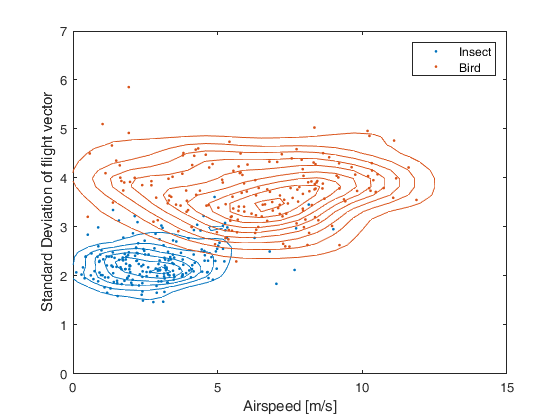

figure; hold on;
scatter(Qan(1,:,1),Qan(1,:,4),'.')
scatter(Qan(2,:,1),Qan(2,:,4),'.')
[f,xi] = ksdensity([Qan(1,:,1)' Qan(1,:,4)']);
f = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),f,'Color',col(1,:))
[f,xi] = ksdensity([Qan(2,:,1)' Qan(2,:,4)']);
f = reshape(f,sqrt(numel(f)),[]);
contour(unique(xi(:,1)),unique(xi(:,2)),f,'Color',col(2,:));
box on; legend({'Insect','Bird'});
xlabel('Airspeed [m/s]'); ylabel('Standard Deviation of flight vector');
axis([0 15 0 7])